clc
clear all

## 数据导入（单面）

dataC = importdata("E:\FS082-2\FS082-2-1L.txt");
dataD = importdata("E:\FS082-2\FS082-2-1R.txt");
data = [dataC;dataD];
x0 = data(:,2);
y0 = data(:,3);
z0 = data(:,1);
[y0,z0] = Re(y0,z0);
[x0,z0] = Re(x0,z0);
%%缩放矩阵扩大数据范围
% s = 120/max(abs(x0));
% X = x0(x0>0);
% Y = y0(x0>0);
% A1 = [X,Y,ones(length(X),1)];
% c = [mean(X),mean(Y)];
% A1 = A1*[1,0,-c(1);0,1,-c(2);0,0,1]'*[s,0,0;0,s,0;0,0,1]'*[1,0,c(1);0,1,c(2);0,0,1]';
% X = A1(:,1); Y = A1(:,2);
% X0 = x0(x0<0);
% Y0 = y0(x0<0);
% A0 = [X0,Y0,ones(length(X0),1)];
% c = [mean(X0),mean(Y0)];
% A0 = A0*[1,0,-c(1);0,1,-c(2);0,0,1]'*[s,0,0;0,s,0;0,0,1]'*[1,0,c(1);0,1,c(2);0,0,1]';
% X0 = A0(:,1); Y0 = A0(:,2);
% x0 = [X;X0]; y0 = [Y;Y0];
ImpData = [x0,y0,z0];

## 数据导入（双面）

% dataC = importdata("E:\FS082-2\FS082-2-1L.txt");
% dataD = importdata("E:\FS082-2\FS082-2-1R.txt");
% dataA = importdata("E:\FS082-2\FS082-2-2R2.txt");
% dataB = importdata("E:\FS082-2\FS082-2-2L2.txt");
% %配对A-C B-D
% x0 = [dataC(:,2);-dataA(:,2)]; y0 = [dataC(:,1);dataA(:,1)]; z0 = [dataC(:,3);dataA(:,3)];
% x1 = [dataD(:,2);-dataB(:,2)]; y1 = [dataD(:,1);dataB(:,1)]; z1 = [dataD(:,3);dataB(:,3)];
% x = [x0;x1];
% y = [y0;y1];
% z = [z0;z1];
% [y,z] = Re(y,z);
% ImpData = [x,y,z];

## 拟合

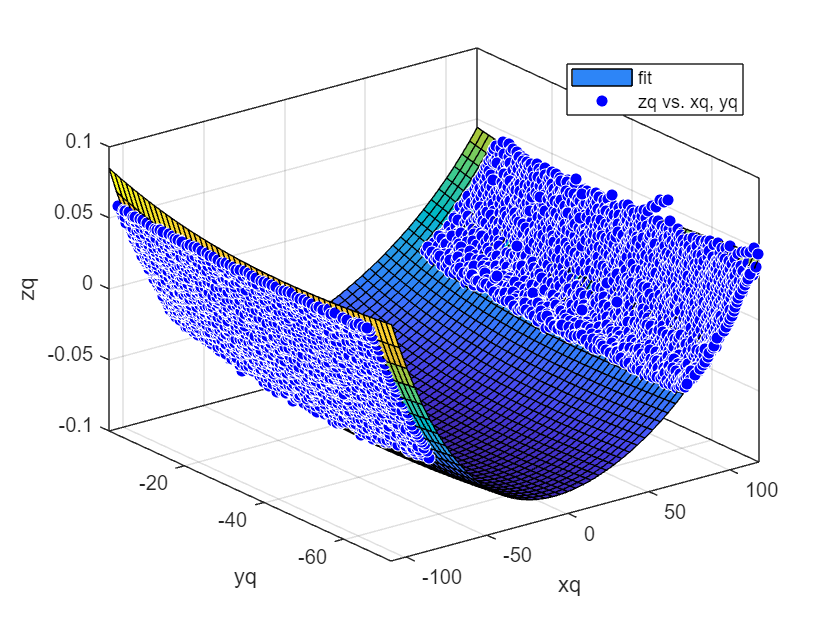

d = 1;%网格大小
[xq, yq, zq] = PreprocessDate(ImpData,d);
%% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-0.061196 + 0.0013399*Y + 2.1595e-05*Y*Y + 1.2566e-07*Y*Y*Y + 2.9062e-10*Y*Y*Y*Y + -3.1376e-08*X*Y + -1.3062e-08*X*Y*Y + 3.2257e-11*X*Y*Y*Y + -2.2491e-08*X*X*Y + -1.3344e-10*X*X*Y*Y + -1.6885e-10*X*X*X*Y + 2.3922e-10*X*X*X*X 


disp(gof)

           sse: 0.0313
       rsquare: 0.9917
           dfe: 5545
    adjrsquare: 0.9917
          rmse: 0.0024



## 单面处理

% data = dataD;
% x0 = data(:,2);
% y0 = data(:,3);
% z0 = data(:,1);
% [y0,z0] = Re(y0,z0);
% [x0,z0] = Re(x0,z0);
% ImpData = [x0,y0,z0];
% d = 1;%网格大小
% [xq, yq, zq] = PreprocessDate(ImpData,d);
% %% 拟合
% n = 4;%拟合方程次数
% [f  gof] = createFit(xq, yq, zq, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)